clear;
N = 10;
theta = linspace(0,2*pi, N);

x = cos(theta);
y = sin(theta);

M1 = (rand(1,numel(theta))-.5)*.005;
M2 = (rand(1,numel(theta))-.5)*.005;

z = ifft(M1);
n = ifft(M2);

syms p s a b c d mu nu NN ps(s) psp(s)

eq1 = (p-a+4*mu*sin(pi*s/NN)^2)*(p - d + 4*nu *sin(pi*s/NN)^2) == b * c;
p = solve(eq1, p);

ps(s) = simplify(subs(p(1), [a,b,c,d,mu,nu,NN],[1,-4,1,-2,.05,2.5,N]));
psp(s) = simplify(subs(p(2), [a,b,c,d,mu,nu,NN],[1,-4,1,-2,.05,2.5,N]));

ps = double(ps(1:N));
psp = double(psp(1:N));

zs = zeros(1,N)

zs =      0     0     0     0     0     0     0     0     0     0


ns = zeros(1,N)

ns =      0     0     0     0     0     0     0     0     0     0


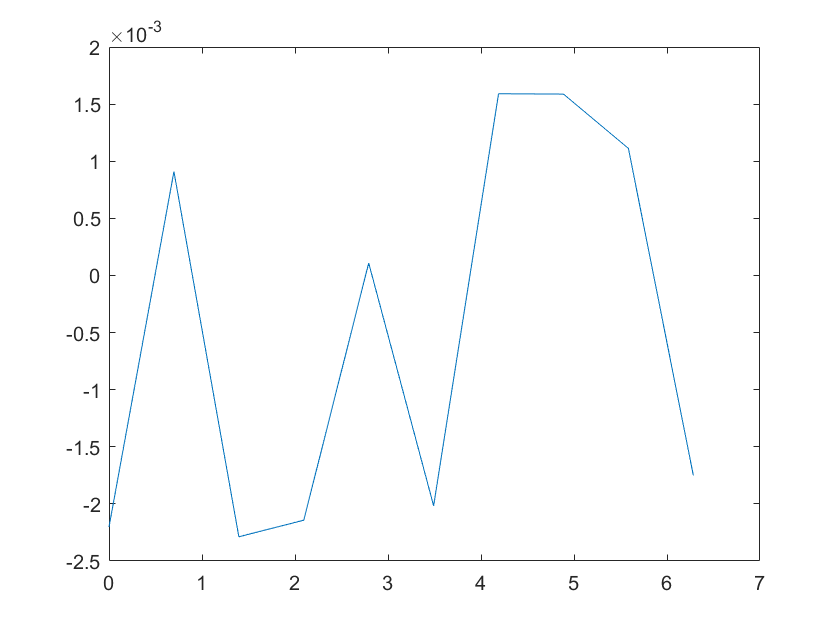

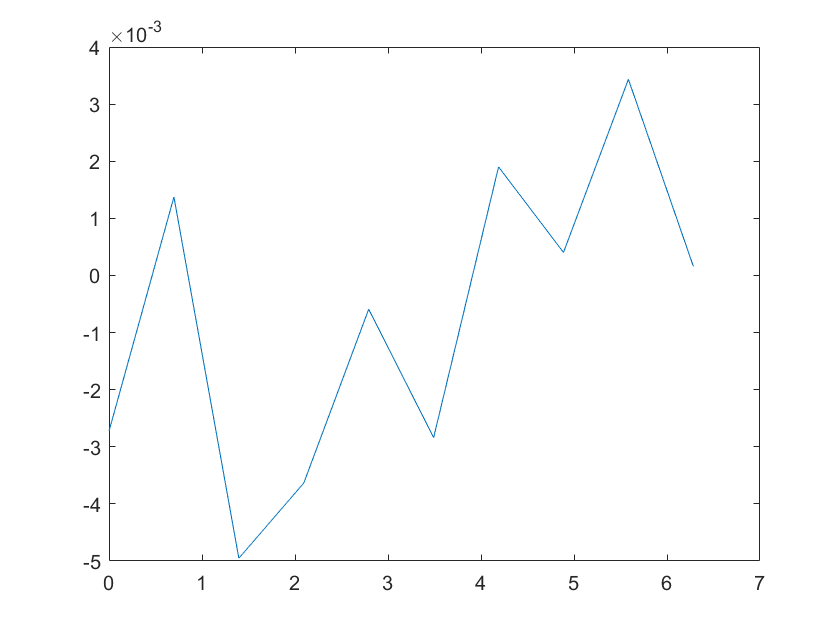

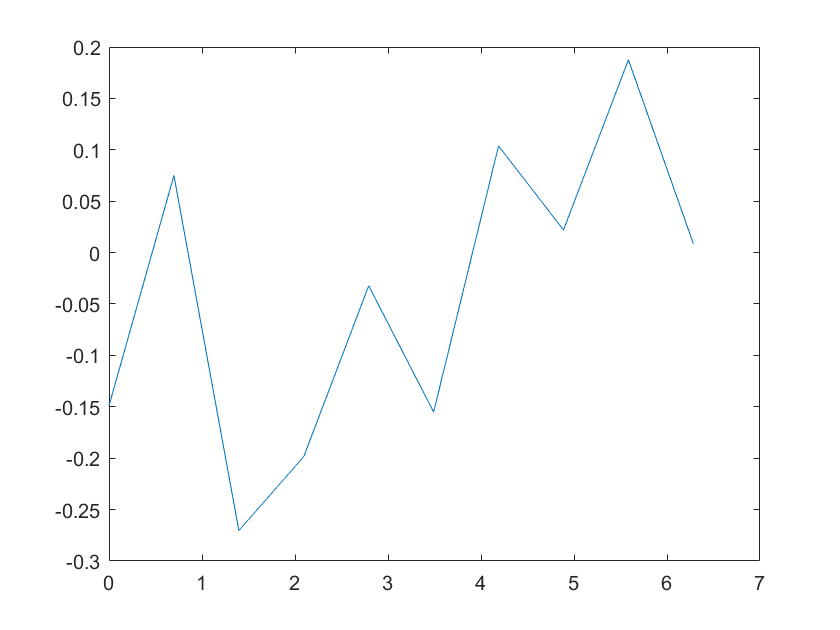

b = -4;

for i=1:N
    
    As = double((n(i) * b - z(i) * psp(i))/(ps(i)-psp(i)));
    Bs = double(-(n(i) * b - z(i) * ps(i))/(ps(i)-psp(i)));
    Cs = double((n(i) * b *ps(i) - z(i) * psp(i) * ps(i))/(b*(ps(i)-psp(i))));
    Ds = double(-psp(i) * (n(i)*b - z(i) * ps(i))/(b*(ps(i)-psp(i))));
    
    zs(i) = double(As * exp(ps(i)) + Bs * exp(psp(i)));
    ns(i) = double(Cs * exp(ps(i)) + Ds * exp(psp(i)));
    
end

xr = fft(zs);
yr = fft(ns);

v = VideoWriter("FFT_test.mp4","MPEG-4");

open(v);
h = figure;

for t=0:0.1:20
    
    
    
end
